# **Robust Design Approach**

clear all
load('parameters.mat');

#### **POLE ALLOCATION #1**

ssRobust.Ki = ssRobust.Ki1;
ssRobust.K = ssRobust.K1;

simul.stepdeg = 40;
ssRobust_simul.pole_1.deg_40 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

% only step where performances are required
stepinfo(ssRobust_simul.pole_1.deg_40.thl_meas.signals.values,ssRobust_simul.pole_1.deg_40.thl_meas.time,simul.stepdeg)

ans = struct with fields:
         RiseTime: 0.0334
    TransientTime: 1.2463
     SettlingTime: 1.2463
      SettlingMin: 36.3600
      SettlingMax: 50.7600
        Overshoot: 26.9000
       Undershoot: 0
             Peak: 50.7600
         PeakTime: 1.0830


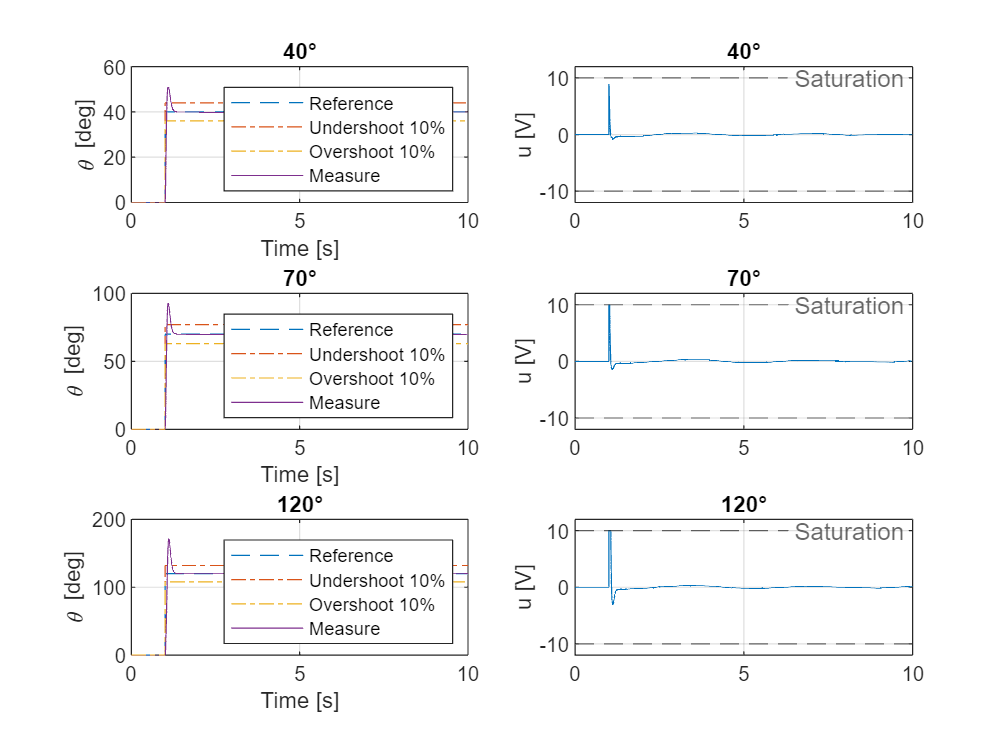


simul.stepdeg = 70;
ssRobust_simul.pole_1.deg_70 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

simul.stepdeg = 120;
ssRobust_simul.pole_1.deg_120 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

figure
subplot(3,2,1)
plot(ssRobust_simul.pole_1.deg_40.thref.time, ssRobust_simul.pole_1.deg_40.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_1.deg_40.thref.time, ssRobust_simul.pole_1.deg_40.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_1.deg_40.thref.time, ssRobust_simul.pole_1.deg_40.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_1.deg_40.thl_meas.time, ssRobust_simul.pole_1.deg_40.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('40°')
grid on

subplot(3,2,3)
plot(ssRobust_simul.pole_1.deg_70.thref.time, ssRobust_simul.pole_1.deg_70.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_1.deg_70.thref.time, ssRobust_simul.pole_1.deg_70.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_1.deg_70.thref.time, ssRobust_simul.pole_1.deg_70.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_1.deg_70.thl_meas.time, ssRobust_simul.pole_1.deg_70.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('70°')
grid on

subplot(3,2,5)
plot(ssRobust_simul.pole_1.deg_120.thref.time, ssRobust_simul.pole_1.deg_120.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_1.deg_120.thref.time, ssRobust_simul.pole_1.deg_120.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_1.deg_120.thref.time, ssRobust_simul.pole_1.deg_120.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_1.deg_120.thl_meas.time, ssRobust_simul.pole_1.deg_120.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('120°')
grid on

subplot(3,2,2)
plot(ssRobust_simul.pole_1.deg_40.u.time, ssRobust_simul.pole_1.deg_40.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('40°')
grid on
subplot(3,2,4)
plot(ssRobust_simul.pole_1.deg_70.u.time, ssRobust_simul.pole_1.deg_70.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('70°')
grid on
subplot(3,2,6)
plot(ssRobust_simul.pole_1.deg_120.u.time, ssRobust_simul.pole_1.deg_120.u.signals.values);
hold on;
title('120°')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
grid on

#### **POLE ALLOCATION #2**

ssRobust.Ki = ssRobust.Ki2;
ssRobust.K = ssRobust.K2;

simul.stepdeg = 40;
ssRobust_simul.pole_2.deg_40 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

% only step where performances are required
stepinfo(ssRobust_simul.pole_2.deg_40.thl_meas.signals.values,ssRobust_simul.pole_2.deg_40.thl_meas.time,simul.stepdeg)

ans = struct with fields:
         RiseTime: 0.0581
    TransientTime: 1.5193
     SettlingTime: 1.5193
      SettlingMin: 36.1800
      SettlingMax: 46.8000
        Overshoot: 17.0000
       Undershoot: 0
             Peak: 46.8000
         PeakTime: 1.1430


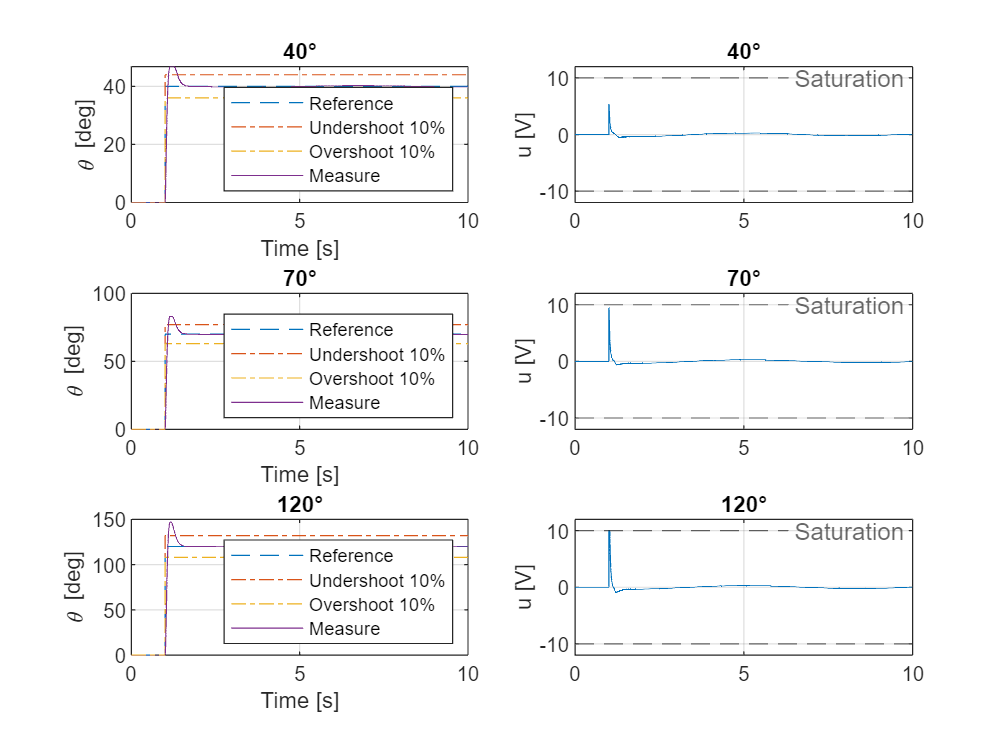


simul.stepdeg = 70;
ssRobust_simul.pole_2.deg_70 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

simul.stepdeg = 120;
ssRobust_simul.pole_2.deg_120 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

figure
subplot(3,2,1)
plot(ssRobust_simul.pole_2.deg_40.thref.time, ssRobust_simul.pole_2.deg_40.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_2.deg_40.thref.time, ssRobust_simul.pole_2.deg_40.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_2.deg_40.thref.time, ssRobust_simul.pole_2.deg_40.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_2.deg_40.thl_meas.time, ssRobust_simul.pole_2.deg_40.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('40°')
grid on

subplot(3,2,3)
plot(ssRobust_simul.pole_2.deg_70.thref.time, ssRobust_simul.pole_2.deg_70.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_2.deg_70.thref.time, ssRobust_simul.pole_2.deg_70.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_2.deg_70.thref.time, ssRobust_simul.pole_2.deg_70.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_2.deg_70.thl_meas.time, ssRobust_simul.pole_2.deg_70.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('70°')
grid on

subplot(3,2,5)
plot(ssRobust_simul.pole_2.deg_120.thref.time, ssRobust_simul.pole_2.deg_120.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_2.deg_120.thref.time, ssRobust_simul.pole_2.deg_120.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_2.deg_120.thref.time, ssRobust_simul.pole_2.deg_120.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_2.deg_120.thl_meas.time, ssRobust_simul.pole_2.deg_120.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('120°')
grid on

subplot(3,2,2)
plot(ssRobust_simul.pole_2.deg_40.u.time, ssRobust_simul.pole_2.deg_40.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('40°')
grid on
subplot(3,2,4)
plot(ssRobust_simul.pole_2.deg_70.u.time, ssRobust_simul.pole_2.deg_70.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('70°')
grid on
subplot(3,2,6)
plot(ssRobust_simul.pole_2.deg_120.u.time, ssRobust_simul.pole_2.deg_120.u.signals.values);
hold on;
title('120°')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
grid on

#### **POLE ALLOCATION #3**

ssRobust.Ki = ssRobust.Ki3;
ssRobust.K = ssRobust.K3;

simul.stepdeg = 40;
ssRobust_simul.pole_3.deg_40 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

% only step where performances are required
stepinfo(ssRobust_simul.pole_3.deg_40.thl_meas.signals.values,ssRobust_simul.pole_3.deg_40.thl_meas.time,simul.stepdeg)

ans = struct with fields:
         RiseTime: 0.0240
    TransientTime: 1.1903
     SettlingTime: 1.1903
      SettlingMin: 36.9000
      SettlingMax: 50.7600
        Overshoot: 26.9000
       Undershoot: 0
             Peak: 50.7600
         PeakTime: 1.0690


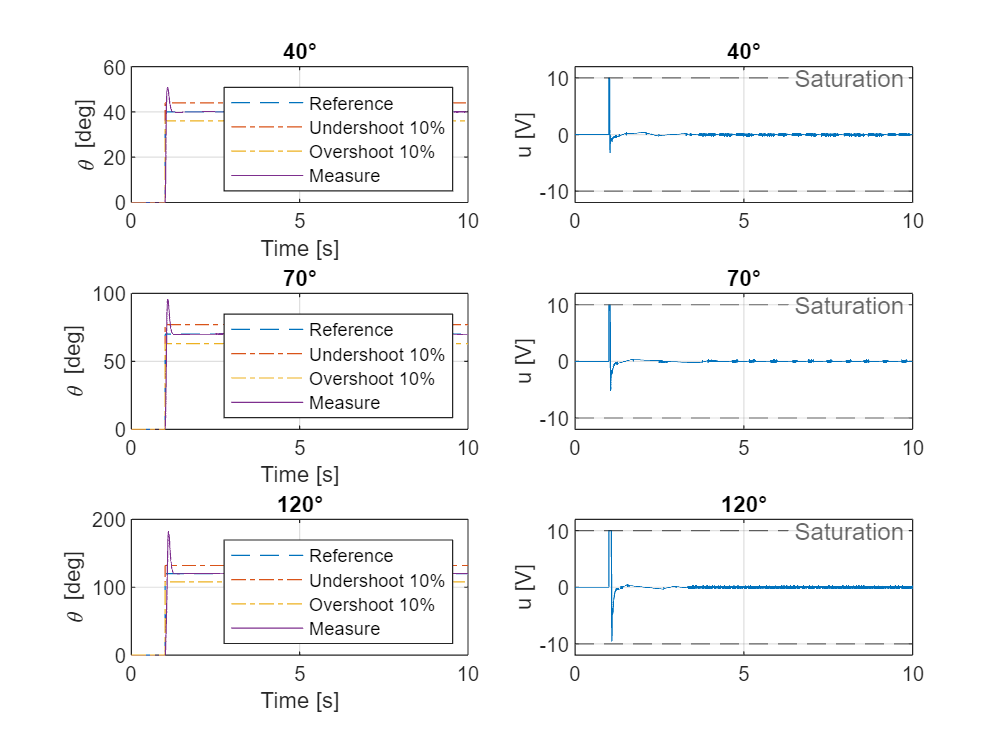


simul.stepdeg = 70;
ssRobust_simul.pole_3.deg_70 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

simul.stepdeg = 120;
ssRobust_simul.pole_3.deg_120 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

figure
subplot(3,2,1)
plot(ssRobust_simul.pole_3.deg_40.thref.time, ssRobust_simul.pole_3.deg_40.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_3.deg_40.thref.time, ssRobust_simul.pole_3.deg_40.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_3.deg_40.thref.time, ssRobust_simul.pole_3.deg_40.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_3.deg_40.thl_meas.time, ssRobust_simul.pole_3.deg_40.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('40°')
grid on

subplot(3,2,3)
plot(ssRobust_simul.pole_3.deg_70.thref.time, ssRobust_simul.pole_3.deg_70.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_3.deg_70.thref.time, ssRobust_simul.pole_3.deg_70.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_3.deg_70.thref.time, ssRobust_simul.pole_3.deg_70.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_3.deg_70.thl_meas.time, ssRobust_simul.pole_3.deg_70.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('70°')
grid on

subplot(3,2,5)
plot(ssRobust_simul.pole_3.deg_120.thref.time, ssRobust_simul.pole_3.deg_120.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_3.deg_120.thref.time, ssRobust_simul.pole_3.deg_120.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_3.deg_120.thref.time, ssRobust_simul.pole_3.deg_120.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_3.deg_120.thl_meas.time, ssRobust_simul.pole_3.deg_120.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('120°')
grid on

subplot(3,2,2)
plot(ssRobust_simul.pole_3.deg_40.u.time, ssRobust_simul.pole_3.deg_40.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('40°')
grid on
subplot(3,2,4)
plot(ssRobust_simul.pole_3.deg_70.u.time, ssRobust_simul.pole_3.deg_70.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('70°')
grid on
subplot(3,2,6)
plot(ssRobust_simul.pole_3.deg_120.u.time, ssRobust_simul.pole_3.deg_120.u.signals.values);
hold on;
title('120°')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
grid on

#### **POLE ALLOCATION #4**

ssRobust.Ki = ssRobust.Ki4;
ssRobust.K = ssRobust.K4;

simul.stepdeg = 40;
ssRobust_simul.pole_4.deg_40 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

% only step where performances are required
stepinfo(ssRobust_simul.pole_4.deg_40.thl_meas.signals.values,ssRobust_simul.pole_4.deg_40.thl_meas.time,simul.stepdeg)

ans = struct with fields:
         RiseTime: 0.0228
    TransientTime: 1.1703
     SettlingTime: 1.1703
      SettlingMin: 37.4400
      SettlingMax: 52.2000
        Overshoot: 30.5000
       Undershoot: 0
             Peak: 52.2000
         PeakTime: 1.0670


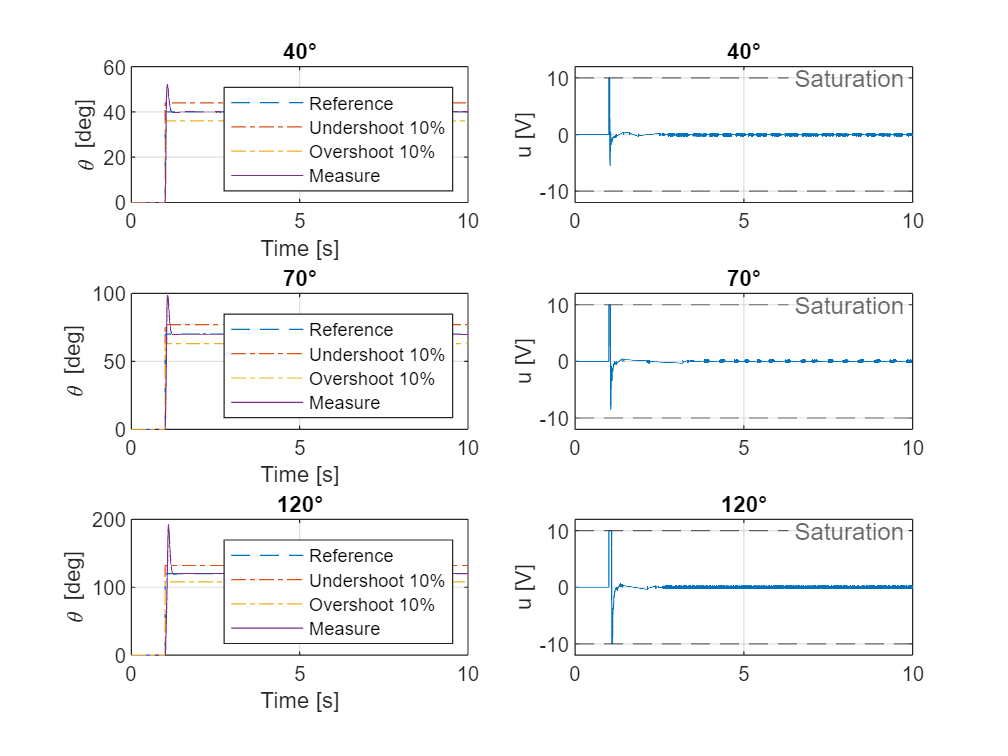


simul.stepdeg = 70;
ssRobust_simul.pole_4.deg_70 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

simul.stepdeg = 120;
ssRobust_simul.pole_4.deg_120 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

figure
subplot(3,2,1)
plot(ssRobust_simul.pole_4.deg_40.thref.time, ssRobust_simul.pole_4.deg_40.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_4.deg_40.thref.time, ssRobust_simul.pole_4.deg_40.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_4.deg_40.thref.time, ssRobust_simul.pole_4.deg_40.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_4.deg_40.thl_meas.time, ssRobust_simul.pole_4.deg_40.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('40°')
grid on

subplot(3,2,3)
plot(ssRobust_simul.pole_4.deg_70.thref.time, ssRobust_simul.pole_4.deg_70.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_4.deg_70.thref.time, ssRobust_simul.pole_4.deg_70.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_4.deg_70.thref.time, ssRobust_simul.pole_4.deg_70.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_4.deg_70.thl_meas.time, ssRobust_simul.pole_4.deg_70.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('70°')
grid on

subplot(3,2,5)
plot(ssRobust_simul.pole_4.deg_120.thref.time, ssRobust_simul.pole_4.deg_120.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_4.deg_120.thref.time, ssRobust_simul.pole_4.deg_120.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_4.deg_120.thref.time, ssRobust_simul.pole_4.deg_120.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_4.deg_120.thl_meas.time, ssRobust_simul.pole_4.deg_120.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('120°')
grid on

subplot(3,2,2)
plot(ssRobust_simul.pole_4.deg_40.u.time, ssRobust_simul.pole_4.deg_40.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('40°')
grid on
subplot(3,2,4)
plot(ssRobust_simul.pole_4.deg_70.u.time, ssRobust_simul.pole_4.deg_70.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('70°')
grid on
subplot(3,2,6)
plot(ssRobust_simul.pole_4.deg_120.u.time, ssRobust_simul.pole_4.deg_120.u.signals.values);
hold on;
title('120°')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
grid on

#### **POLE ALLOCATION #5 CUSTOM POLES**

ssRobust.Ki = ssRobust.Ki5;
ssRobust.K = ssRobust.K5;

simul.stepdeg = 40;
ssRobust_simul.pole_5.deg_40 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

% only step where performances are required
stepinfo(ssRobust_simul.pole_5.deg_40.thl_meas.signals.values,ssRobust_simul.pole_5.deg_40.thl_meas.time,simul.stepdeg)

ans = struct with fields:
         RiseTime: 0.0219
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: -1.6978e+03
      SettlingMax: 1.6355e+03
        Overshoot: 3.9887e+03
       Undershoot: 4.2444e+03
             Peak: 1.6978e+03
         PeakTime: 9.1730


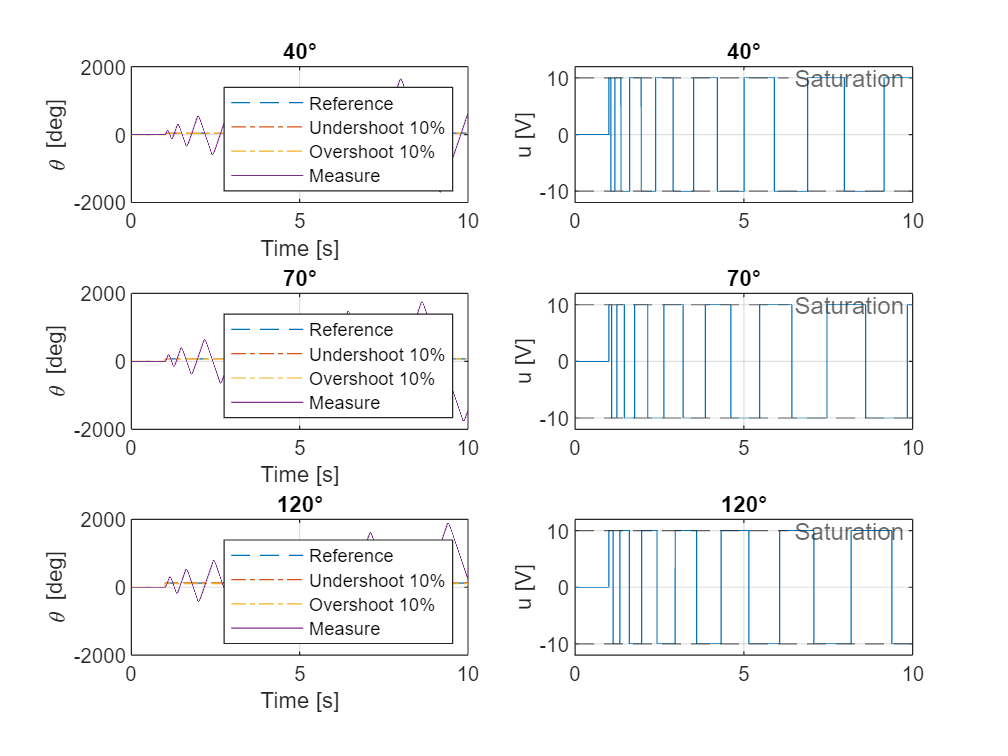


simul.stepdeg = 70;
ssRobust_simul.pole_5.deg_70 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

simul.stepdeg = 120;
ssRobust_simul.pole_5.deg_120 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');

figure
subplot(3,2,1)
plot(ssRobust_simul.pole_5.deg_40.thref.time, ssRobust_simul.pole_5.deg_40.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_5.deg_40.thref.time, ssRobust_simul.pole_5.deg_40.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_5.deg_40.thref.time, ssRobust_simul.pole_5.deg_40.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_5.deg_40.thl_meas.time, ssRobust_simul.pole_5.deg_40.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('40°')
grid on

subplot(3,2,3)
plot(ssRobust_simul.pole_5.deg_70.thref.time, ssRobust_simul.pole_5.deg_70.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_5.deg_70.thref.time, ssRobust_simul.pole_5.deg_70.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_5.deg_70.thref.time, ssRobust_simul.pole_5.deg_70.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_5.deg_70.thl_meas.time, ssRobust_simul.pole_5.deg_70.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('70°')
grid on

subplot(3,2,5)
plot(ssRobust_simul.pole_5.deg_120.thref.time, ssRobust_simul.pole_5.deg_120.thref.signals.values,'--');
hold on;
plot(ssRobust_simul.pole_5.deg_120.thref.time, ssRobust_simul.pole_5.deg_120.thref.signals.values*1.10,'-.');
plot(ssRobust_simul.pole_5.deg_120.thref.time, ssRobust_simul.pole_5.deg_120.thref.signals.values*0.9,'-.');
plot(ssRobust_simul.pole_5.deg_120.thl_meas.time, ssRobust_simul.pole_5.deg_120.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('120°')
grid on

subplot(3,2,2)
plot(ssRobust_simul.pole_5.deg_40.u.time, ssRobust_simul.pole_5.deg_40.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('40°')
grid on
subplot(3,2,4)
plot(ssRobust_simul.pole_5.deg_70.u.time, ssRobust_simul.pole_5.deg_70.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('70°')
grid on
subplot(3,2,6)
plot(ssRobust_simul.pole_5.deg_120.u.time, ssRobust_simul.pole_5.deg_120.u.signals.values);
hold on;
title('120°')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
grid on

save('ssRobust_simul.mat','ssRobust_simul');